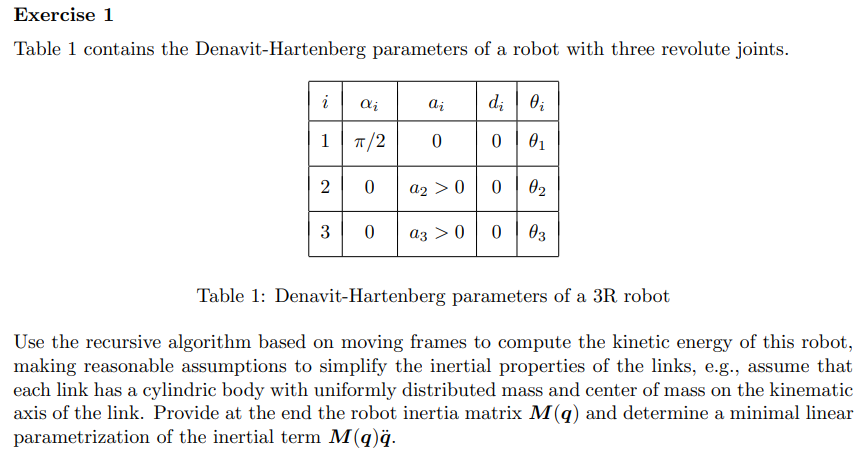

syms theta_1 theta_2 theta_3 a_2 a_3 q_dot_1 q_dot_2 q_dot_3 real
syms m_1 m_2 m_3  q1 q2 q3 positive

% DH table: [alpha, a, d, theta]
DH_table = [pi/2  0   0   q1;
             0   a_2  0   q2;
             0   a_3  0   q3;];

num_joints = 3;
qdots = [q_dot_1; q_dot_2; q_dot_3];
m = [m_1; m_2; m_3];

% Position of the CoM in each local frame (example: center along x-axis of each link)
syms r1x r2x r3x real
rc = [r1x 0   0;
      0   r2x 0;
      0   0   r3x];

% Prismatic joints (none in this case)
prismatic_indices = [];

% Inertia matrices (example: identity for simplicity)
I1 = eye(3); I2 = eye(3); I3 = eye(3);
I = [I1, I2, I3];

% Call the moving frames algorithm function
[w, v, vc, T] = moving_frames_algorithm(num_joints, DH_table, qdots, m, rc, prismatic_indices, I);

---- Starting the Moving Frames Algorithm ----
Number of joints: 3
The value of w_1 is:


$$\left(\begin{array}{c} {\dot{q}}_{1}\,\sin\left(q_{1}\right)\\ {\dot{q}}_{1}\,\cos\left(q_{1}\right)\\ 0 \end{array}\right)$$

The value of v_1 is:


$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

The value of vc_1 is:


$$\left(\begin{array}{c} 0\\ 0\\ -{\dot{q}}_{1}\,\mathrm{r1x}\,\cos\left(q_{1}\right) \end{array}\right)$$

The value of T_1 is:


$$\frac{{{\dot{q}}_{1}}^{2}\,\left(-m_{1}\,{\mathrm{r1x}}^{2}\,{\sin\left(q_{1}\right)}^{2}+m_{1}\,{\mathrm{r1x}}^{2}+1\right)}{2}$$

The value of w_2 is:


$$\left(\begin{array}{c} {\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+{\dot{q}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ {\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-{\dot{q}}_{1}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ {\dot{q}}_{2} \end{array}\right)$$

The value of v_2 is:


$$\left(\begin{array}{c} a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ a_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\\ -a_{2}\,\cos\left(q_{2}\right)\,\left({\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-{\dot{q}}_{1}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)-a_{2}\,\sin\left(q_{2}\right)\,\left({\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+{\dot{q}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\right) \end{array}\right)$$

The value of vc_2 is:


$$\begin{array}{l} \left(\begin{array}{c} a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)-{\dot{q}}_{2}\,\mathrm{r2x}\\ a_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\\ \mathrm{r2x}\,\sigma_{1}-a_{2}\,\cos\left(q_{2}\right)\,\left({\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-{\dot{q}}_{1}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)-a_{2}\,\sin\left(q_{2}\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+{\dot{q}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) \end{array}$$

The value of T_2 is:


$$\frac{{{\dot{q}}_{1}}^{2}}{2}+\frac{{{\dot{q}}_{2}}^{2}}{2}+\frac{{a_{2}}^{2}\,m_{2}\,{{\dot{q}}_{1}}^{2}}{4}+\frac{{a_{2}}^{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{m_{2}\,{{\dot{q}}_{1}}^{2}\,{\mathrm{r2x}}^{2}}{4}+\frac{m_{2}\,{{\dot{q}}_{2}}^{2}\,{\mathrm{r2x}}^{2}}{2}+\frac{{a_{2}}^{2}\,m_{2}\,{{\dot{q}}_{1}}^{2}\,\cos\left(2\,q_{1}\right)}{4}-\frac{m_{2}\,{{\dot{q}}_{1}}^{2}\,{\mathrm{r2x}}^{2}\,\cos\left(2\,q_{1}+2\,q_{2}\right)}{4}-\frac{a_{2}\,m_{2}\,{{\dot{q}}_{1}}^{2}\,\mathrm{r2x}\,\sin\left(q_{2}\right)}{2}-a_{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}\,\mathrm{r2x}\,\sin\left(q_{2}\right)-\frac{a_{2}\,m_{2}\,{{\dot{q}}_{1}}^{2}\,\mathrm{r2x}\,\sin\left(2\,q_{1}+q_{2}\right)}{2}$$

The value of w_3 is:


$$\begin{array}{l} \left(\begin{array}{c} \cos\left(q_{3}\right)\,\sigma_{2}+\sin\left(q_{3}\right)\,\sigma_{1}\\ \cos\left(q_{3}\right)\,\sigma_{1}-\sin\left(q_{3}\right)\,\sigma_{2}\\ {\dot{q}}_{2}+{\dot{q}}_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-{\dot{q}}_{1}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}={\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+{\dot{q}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) \end{array}$$

The value of v_3 is:


$$\begin{array}{l} \left(\begin{array}{c} a_{3}\,\sin\left(q_{3}\right)\,\left({\dot{q}}_{2}+{\dot{q}}_{3}\right)+a_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+a_{2}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ a_{3}\,\cos\left(q_{3}\right)\,\left({\dot{q}}_{2}+{\dot{q}}_{3}\right)+a_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ -a_{2}\,\cos\left(q_{2}\right)\,\sigma_{1}-a_{2}\,\sin\left(q_{2}\right)\,\sigma_{2}-a_{3}\,\cos\left(q_{3}\right)\,\left(\cos\left(q_{3}\right)\,\sigma_{1}-\sin\left(q_{3}\right)\,\sigma_{2}\right)-a_{3}\,\sin\left(q_{3}\right)\,\left(\cos\left(q_{3}\right)\,\sigma_{2}+\sin\left(q_{3}\right)\,\sigma_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-{\dot{q}}_{1}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}={\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+{\dot{q}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) \end{array}$$

The value of vc_3 is:


$$\begin{array}{l} \left(\begin{array}{c} \mathrm{r3x}\,\sigma_{1}+a_{3}\,\sin\left(q_{3}\right)\,\left({\dot{q}}_{2}+{\dot{q}}_{3}\right)+a_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+a_{2}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ a_{3}\,\cos\left(q_{3}\right)\,\left({\dot{q}}_{2}+{\dot{q}}_{3}\right)-\mathrm{r3x}\,\sigma_{2}+a_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ -a_{2}\,\cos\left(q_{2}\right)\,\sigma_{3}-a_{2}\,\sin\left(q_{2}\right)\,\sigma_{4}-a_{3}\,\cos\left(q_{3}\right)\,\sigma_{1}-a_{3}\,\sin\left(q_{3}\right)\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{3}\right)\,\sigma_{3}-\sin\left(q_{3}\right)\,\sigma_{4}\\ \sigma_{2}=\cos\left(q_{3}\right)\,\sigma_{4}+\sin\left(q_{3}\right)\,\sigma_{3}\\ \sigma_{3}={\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-{\dot{q}}_{1}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{4}={\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+{\dot{q}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) \end{array}$$

The value of T_3 is:


$${\dot{q}}_{2}\,{\dot{q}}_{3}+\frac{{{\dot{q}}_{1}}^{2}}{2}+\frac{{{\dot{q}}_{2}}^{2}}{2}+\frac{{{\dot{q}}_{3}}^{2}}{2}+\frac{{a_{2}}^{2}\,m_{3}\,{{\dot{q}}_{1}}^{2}}{4}+\frac{{a_{2}}^{2}\,m_{3}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{{a_{3}}^{2}\,m_{3}\,{{\dot{q}}_{1}}^{2}}{4}+\frac{{a_{3}}^{2}\,m_{3}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{{a_{3}}^{2}\,m_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{m_{3}\,{{\dot{q}}_{1}}^{2}\,{\mathrm{r3x}}^{2}}{2}+{a_{3}}^{2}\,m_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}+\frac{{a_{2}}^{2}\,m_{3}\,{{\dot{q}}_{1}}^{2}\,\cos\left(2\,q_{1}\right)}{4}+\frac{{a_{3}}^{2}\,m_{3}\,{{\dot{q}}_{1}}^{2}\,\cos\left(2\,q_{1}+2\,q_{2}\right)}{4}+\frac{a_{2}\,a_{3}\,m_{3}\,{{\dot{q}}_{1}}^{2}\,\cos\left(q_{2}\right)}{2}+a_{2}\,a_{3}\,m_{3}\,{{\dot{q}}_{2}}^{2}\,\cos\left(q_{2}\right)+\frac{a_{2}\,a_{3}\,m_{3}\,{{\dot{q}}_{1}}^{2}\,\cos\left(2\,q_{1}+q_{2}\right)}{2}-a_{3}\,m_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\mathrm{r3x}\,\sin\left(q_{1}+q_{2}\right)-a_{3}\,m_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\mathrm{r3x}\,\sin\left(q_{1}+q_{2}\right)+a_{2}\,a_{3}\,m_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\cos\left(q_{2}\right)-a_{2}\,m_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\mathrm{r3x}\,\sin\left(q_{1}\right)$$


disp('=== Kinetic energies T ===');

=== Kinetic energies T ===


for i = 1:num_joints
    fprintf('T{%d} =\n', i);
    disp(T{i});
end

T{1} =


$$\frac{{{\dot{q}}_{1}}^{2}\,\left(-m_{1}\,{\mathrm{r1x}}^{2}\,{\sin\left(q_{1}\right)}^{2}+m_{1}\,{\mathrm{r1x}}^{2}+1\right)}{2}$$

T{2} =


$$\frac{{{\dot{q}}_{1}}^{2}}{2}+\frac{{{\dot{q}}_{2}}^{2}}{2}+\frac{{a_{2}}^{2}\,m_{2}\,{{\dot{q}}_{1}}^{2}}{4}+\frac{{a_{2}}^{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{m_{2}\,{{\dot{q}}_{1}}^{2}\,{\mathrm{r2x}}^{2}}{4}+\frac{m_{2}\,{{\dot{q}}_{2}}^{2}\,{\mathrm{r2x}}^{2}}{2}+\frac{{a_{2}}^{2}\,m_{2}\,{{\dot{q}}_{1}}^{2}\,\cos\left(2\,q_{1}\right)}{4}-\frac{m_{2}\,{{\dot{q}}_{1}}^{2}\,{\mathrm{r2x}}^{2}\,\cos\left(2\,q_{1}+2\,q_{2}\right)}{4}-\frac{a_{2}\,m_{2}\,{{\dot{q}}_{1}}^{2}\,\mathrm{r2x}\,\sin\left(q_{2}\right)}{2}-a_{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}\,\mathrm{r2x}\,\sin\left(q_{2}\right)-\frac{a_{2}\,m_{2}\,{{\dot{q}}_{1}}^{2}\,\mathrm{r2x}\,\sin\left(2\,q_{1}+q_{2}\right)}{2}$$

T{3} =


$${\dot{q}}_{2}\,{\dot{q}}_{3}+\frac{{{\dot{q}}_{1}}^{2}}{2}+\frac{{{\dot{q}}_{2}}^{2}}{2}+\frac{{{\dot{q}}_{3}}^{2}}{2}+\frac{{a_{2}}^{2}\,m_{3}\,{{\dot{q}}_{1}}^{2}}{4}+\frac{{a_{2}}^{2}\,m_{3}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{{a_{3}}^{2}\,m_{3}\,{{\dot{q}}_{1}}^{2}}{4}+\frac{{a_{3}}^{2}\,m_{3}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{{a_{3}}^{2}\,m_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{m_{3}\,{{\dot{q}}_{1}}^{2}\,{\mathrm{r3x}}^{2}}{2}+{a_{3}}^{2}\,m_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}+\frac{{a_{2}}^{2}\,m_{3}\,{{\dot{q}}_{1}}^{2}\,\cos\left(2\,q_{1}\right)}{4}+\frac{{a_{3}}^{2}\,m_{3}\,{{\dot{q}}_{1}}^{2}\,\cos\left(2\,q_{1}+2\,q_{2}\right)}{4}+\frac{a_{2}\,a_{3}\,m_{3}\,{{\dot{q}}_{1}}^{2}\,\cos\left(q_{2}\right)}{2}+a_{2}\,a_{3}\,m_{3}\,{{\dot{q}}_{2}}^{2}\,\cos\left(q_{2}\right)+\frac{a_{2}\,a_{3}\,m_{3}\,{{\dot{q}}_{1}}^{2}\,\cos\left(2\,q_{1}+q_{2}\right)}{2}-a_{3}\,m_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\mathrm{r3x}\,\sin\left(q_{1}+q_{2}\right)-a_{3}\,m_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\mathrm{r3x}\,\sin\left(q_{1}+q_{2}\right)+a_{2}\,a_{3}\,m_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\cos\left(q_{2}\right)-a_{2}\,m_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\mathrm{r3x}\,\sin\left(q_{1}\right)$$


T = T{1}+T{2}+T{3}

$$T = \begin{array}{l} \frac{{{\dot{q}}_{1}}^{2}\,\left(-m_{1}\,{\mathrm{r1x}}^{2}\,{\sin\left(q_{1}\right)}^{2}+m_{1}\,{\mathrm{r1x}}^{2}+1\right)}{2}+{\dot{q}}_{2}\,{\dot{q}}_{3}+{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}+\frac{{{\dot{q}}_{3}}^{2}}{2}+\frac{{a_{2}}^{2}\,m_{2}\,{{\dot{q}}_{1}}^{2}}{4}+\frac{{a_{2}}^{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{{a_{2}}^{2}\,m_{3}\,{{\dot{q}}_{1}}^{2}}{4}+\frac{{a_{2}}^{2}\,m_{3}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{{a_{3}}^{2}\,m_{3}\,{{\dot{q}}_{1}}^{2}}{4}+\frac{{a_{3}}^{2}\,m_{3}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{{a_{3}}^{2}\,m_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{m_{2}\,{{\dot{q}}_{1}}^{2}\,{\mathrm{r2x}}^{2}}{4}+\frac{m_{2}\,{{\dot{q}}_{2}}^{2}\,{\mathrm{r2x}}^{2}}{2}+\frac{m_{3}\,{{\dot{q}}_{1}}^{2}\,{\mathrm{r3x}}^{2}}{2}+{a_{3}}^{2}\,m_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}+\frac{{a_{2}}^{2}\,m_{2}\,{{\dot{q}}_{1}}^{2}\,\cos\left(2\,q_{1}\right)}{4}+\frac{{a_{2}}^{2}\,m_{3}\,{{\dot{q}}_{1}}^{2}\,\cos\left(2\,q_{1}\right)}{4}+\frac{{a_{3}}^{2}\,m_{3}\,{{\dot{q}}_{1}}^{2}\,\sigma_{1}}{4}-\frac{m_{2}\,{{\dot{q}}_{1}}^{2}\,{\mathrm{r2x}}^{2}\,\sigma_{1}}{4}+\frac{a_{2}\,a_{3}\,m_{3}\,{{\dot{q}}_{1}}^{2}\,\cos\left(q_{2}\right)}{2}+a_{2}\,a_{3}\,m_{3}\,{{\dot{q}}_{2}}^{2}\,\cos\left(q_{2}\right)-\frac{a_{2}\,m_{2}\,{{\dot{q}}_{1}}^{2}\,\mathrm{r2x}\,\sin\left(q_{2}\right)}{2}-a_{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}\,\mathrm{r2x}\,\sin\left(q_{2}\right)+\frac{a_{2}\,a_{3}\,m_{3}\,{{\dot{q}}_{1}}^{2}\,\cos\left(2\,q_{1}+q_{2}\right)}{2}-\frac{a_{2}\,m_{2}\,{{\dot{q}}_{1}}^{2}\,\mathrm{r2x}\,\sin\left(2\,q_{1}+q_{2}\right)}{2}-a_{3}\,m_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\mathrm{r3x}\,\sin\left(q_{1}+q_{2}\right)-a_{3}\,m_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\mathrm{r3x}\,\sin\left(q_{1}+q_{2}\right)+a_{2}\,a_{3}\,m_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\cos\left(q_{2}\right)-a_{2}\,m_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\mathrm{r3x}\,\sin\left(q_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(2\,q_{1}+2\,q_{2}\right) \end{array}$$


% Inertia Matrix
M11 = diff(diff(T, q_dot_1), q_dot_1);
M12 = diff(diff(T, q_dot_1), q_dot_2);
M13 = diff(diff(T, q_dot_1), q_dot_3);

M21 = diff(diff(T, q_dot_2), q_dot_1);
M22 = diff(diff(T, q_dot_2), q_dot_2);
M23 = diff(diff(T, q_dot_2), q_dot_3);

M31 = diff(diff(T, q_dot_3), q_dot_1);
M32 = diff(diff(T, q_dot_3), q_dot_2);
M33 = diff(diff(T, q_dot_3), q_dot_3);

M = [M11, M12, M13; M21, M22, M23; M31, M32, M33]

$$M = \begin{array}{l} \left(\begin{array}{ccc} \frac{{a_{2}}^{2}\,m_{2}}{2}+\frac{{a_{2}}^{2}\,m_{3}}{2}+\frac{{a_{3}}^{2}\,m_{3}}{2}+m_{1}\,{\mathrm{r1x}}^{2}+\frac{m_{2}\,{\mathrm{r2x}}^{2}}{2}+m_{3}\,{\mathrm{r3x}}^{2}-\frac{m_{2}\,{\mathrm{r2x}}^{2}\,\sigma_{2}}{2}+\frac{{a_{2}}^{2}\,m_{2}\,\cos\left(2\,q_{1}\right)}{2}+\frac{{a_{2}}^{2}\,m_{3}\,\cos\left(2\,q_{1}\right)}{2}-m_{1}\,{\mathrm{r1x}}^{2}\,{\sin\left(q_{1}\right)}^{2}+\frac{{a_{3}}^{2}\,m_{3}\,\sigma_{2}}{2}+a_{2}\,a_{3}\,m_{3}\,\cos\left(q_{2}\right)-a_{2}\,m_{2}\,\mathrm{r2x}\,\sin\left(q_{2}\right)+a_{2}\,a_{3}\,m_{3}\,\cos\left(2\,q_{1}+q_{2}\right)-a_{2}\,m_{2}\,\mathrm{r2x}\,\sin\left(2\,q_{1}+q_{2}\right)+3 & \sigma_{3} & -\sigma_{4}\\ \sigma_{3} & {a_{2}}^{2}\,m_{2}+{a_{2}}^{2}\,m_{3}+{a_{3}}^{2}\,m_{3}+m_{2}\,{\mathrm{r2x}}^{2}+2\,a_{2}\,a_{3}\,m_{3}\,\cos\left(q_{2}\right)-2\,a_{2}\,m_{2}\,\mathrm{r2x}\,\sin\left(q_{2}\right)+2 & \sigma_{1}\\ -\sigma_{4} & \sigma_{1} & m_{3}\,{a_{3}}^{2}+1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{3}\,{a_{3}}^{2}+a_{2}\,m_{3}\,\cos\left(q_{2}\right)\,a_{3}+1\\ \sigma_{2}=\cos\left(2\,q_{1}+2\,q_{2}\right)\\ \sigma_{3}=\left(-\sigma_{4}\right)-a_{2}\,m_{3}\,\mathrm{r3x}\,\sin\left(q_{1}\right)\\ \sigma_{4}=a_{3}\,m_{3}\,\mathrm{r3x}\,\sin\left(q_{1}+q_{2}\right) \end{array}$$

#### Utils function


function A = DHMatrix_M(row)
    alpha = row(1);
    a = row(2);
    d = row(3);
    theta = row(4);

    A = [cos(theta),            -sin(theta),           0,              a;
         sin(theta)*cos(alpha), cos(theta)*cos(alpha), -sin(alpha),   -sin(alpha)*d;
         sin(theta)*sin(alpha), cos(theta)*sin(alpha), cos(alpha),    cos(alpha)*d;
         0,                     0,                     0,              1];
end

function [w, v, vc, T] = moving_frames_algorithm(num_joints, DH, qdots, m, rc, prismatic_indices, I)
    % This function performs the moving frame algorithm and returns the
    % vectors w, v, vc, and the values of T for each joint
    %
    % Inputs:
    %   - num_joints        = An integer representing the number of links of the robot
    %   - DH                = The DH matrix of the robot in the order [alpha, a, d, theta]
    %   - qdots             = A vector containing qdots ex: [qd1; qd2; qd3]
    %   - m                 = a vector of masses [m1 ; ... ; mn]
    %   - rc                = a vector containing the values ^ir_{ci} that is the distance
    %                         between the i-th CoM from the i-th reference frame
    %   - prismatic_indices = A list containing the list of prismatic indices, ex for a PPR = [1,2]
    %   - I                 = a vector of 3 by 3 matrices [I1, .., In] which are the baricentric inertia matrices
    %
    % Outputs:
    %   - w  = The angular velocity vector for each joint
    %   - v  = The linear velocity vector for each joint
    %   - vc = The velocity of the center of mass for each joint
    %   - T  = The kinetic energy for each joint
    
    % Check that the DH is consistent with the indicated number of joints 
    if size(DH, 1) ~= num_joints
        error('Number of rows in DH matrix should be equal to the number of joints.');
    end

    % Check that rc is consistent with the number of joints 
    if size(rc,2) ~= num_joints
        error('Length of rc vector should be equal to the number of joints.');
    end

    disp("---- Starting the Moving Frames Algorithm ----");

    % Display the number of joints and prismatic indices
    disp(['Number of joints: ', num2str(num_joints)]);
    
    %START THE ALGORITHM:
    v00 = [0; 0; 0];
    w00 = [0; 0; 0];

    % Initialize outputs
    w = zeros(3, num_joints);
    v = zeros(3, num_joints);
    vc = zeros(3, num_joints);
    T = cell(num_joints);
    
    % Start the loop
    for i = 1:num_joints
        In=I(1:3, (i-1)*3+1:i*3);
        
        % Computing sigma for prismatic joints
        if ismember(i, prismatic_indices)
            sigma = 1;
        else
            sigma = 0;
        end

        % Computing A, R, and p
        A = DHMatrix_M(DH(i,:));
        R = A(1:3,1:3);
        p = A(1:3,4);

        r_i = R' * p;

        % Computing omega
        if i == 1
            w_prev = w00;
        else
            w_prev = wi;
        end
        
        % Computing w_i
        wi = R' * (w_prev + (1 - sigma) * [0; 0; qdots(i)]);
        fprintf('The value of w_%d is:', i);
        fprintf('\n');
        disp(wi);

        % Computing v
        if i == 1
            v_prev = v00;
        else
            v_prev = vi;
        end 
        
        % Computing v_i
        vi = R' * (v_prev + sigma * [0; 0; qdots(i)]) + cross(wi, r_i, 1);
        fprintf('The value of v_%d is:', i);
        fprintf('\n');
        disp(vi);

        % Computing vc_i
        vci = vi + cross(wi, rc(:, i));
        fprintf('The value of vc_%d is:', i);
        fprintf('\n');
        disp(vci);

        % Computing T_i
        Ti = simplify(0.5 * m(i) * (vci' * vci) + 0.5 * wi' * In * wi);
        fprintf('The value of T_%d is:', i);
        fprintf('\n');
        disp(Ti)
        T{i} = Ti;
    end
end

